# Tracking Controller Design

This script demonstrates a simple methodology to design a continuous tracking controller $G_c$ represented by the following block diagram. 

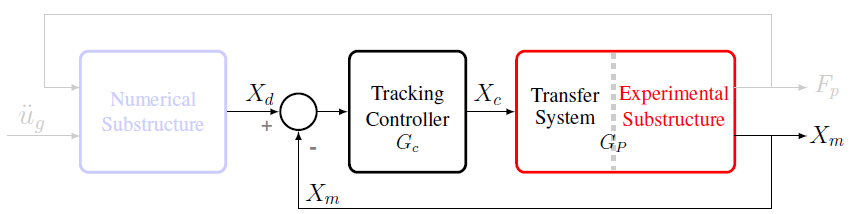        

Proportional-Integral-Derivative (PID) control is a commonly used technique in control. The corresponding control architecture of a PID compensator in parallel form with a first-order derivaltive filter is shown below.

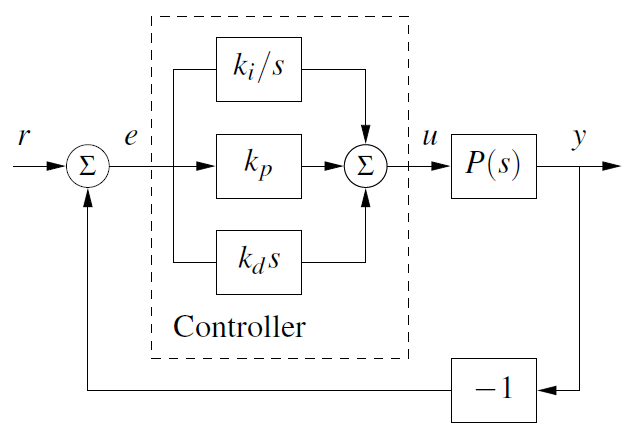           

The open-loop response of the plant *P(s)* is shown below.

clc, clear, close all
b_d = [0 0.4471 0.7412];   r_d = [0.8510 0.3255 0.0980]; y_d = [0.9294  0.6941    0.1255];

load Plant
tt = 0:dt_rths:.12;
[y_p] =  step(G_plant,tt);

figure(1)
p1 = plot([0 tt(end)],[1 1],'k--','linewidth',1.2); grid on, hold on
p2 = plot(tt,y_p,'color',b_d,'linewidth',2);
ylabel('Amplitude ','fontsize',12,'fontweight','bold')
xlabel('Time [sec]','fontsize',12,'fontweight','bold')

The following procedure describes a simple methodology to design a PID controller. This procedure is based on the idea of tuning controllers based on the plant step response using the Ziegler–Nichols step response method.  

## 1. Obtain `a` and $\tau$ which are the intercepts of the tangent of the step response with the coordinate axes. 

Calculate the slope between 2 points of the step response of the plant in order to obtain the parameters `a` and  $\tau$.

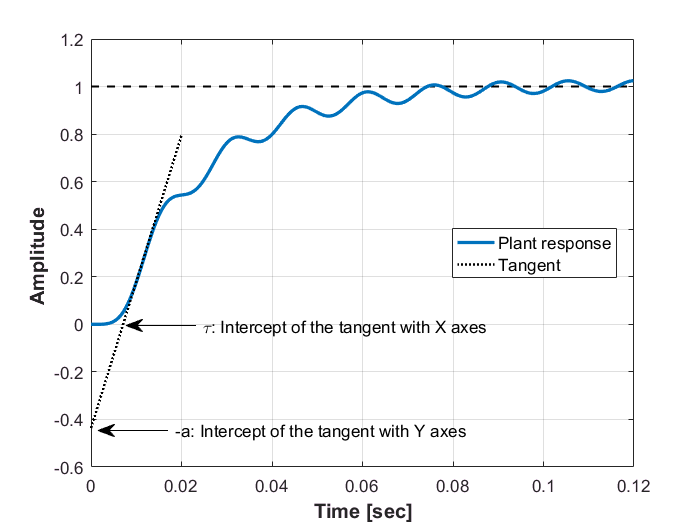

coor= [...
    0.0087    0.0993
    0.0111    0.2471  ];
m = (coor(2,2)-coor(1,2))/(coor(2,1)-coor(1,1));
a = -(coor(1,2)-m*coor(1,1));
tau = a/m;
yy = m*[0:.001:.02]-a;
p4 = plot([0:.001:.02],yy,'k:','linewidth',1.5);

x = [0.28 0.18]; y = [0.38 0.38];
annotation('textarrow',x,y,'String','\tau: Intercept of the tangent with X axes')
x = [0.24 0.14]; y = [0.18 0.18];
annotation('textarrow',x,y,'String','-a: Intercept of the tangent with Y axes')
legend([p2,p4],{'Plant response','Tangent '},'Location','East','fontsize',10)

## 2. Ziegler-Nichols tunning rules for the step response in terms of the  `a` and $\tau$. 

The PID controller transfer function in parallel form with a $1^{\mathrm{st}}$ order derivative filter is:


$$G_{ C }(s)=k_{ P }+\frac { { k }_{ i } }{ s } +\frac { k_{ D }s }{ Tf\cdot s+1 } $$


The scalars `Kp`, `Ki`, `Kd`, and Tf specify the proportional gain, integral gain, derivative gain, and filter time constant. Simple tunning rules that give an initial good performance are shown in the following table:

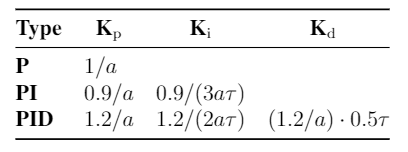

Type = {'P';'PI';'PID'};
Kp = [1/a;   0.9/a;            1.2/a];
Ki = [0;    (0.9/a)/(3*tau);  (1.2/a)/(2*tau)];
Kd = [0;     0;               (1.2/a)*(0.5*tau)];

Kp = round(100*Kp)/100;
Ki = round(100*Ki)/100;
Kd = round(10000*Kd)/10000;

Controller = table(Kp,Ki,Kd,'RowNames',Type)

Controller =             Kp       Ki        Kd  
           ____    ______    ______

    P      2.29         0         0
    PI     2.06     96.98         0
    PID    2.75    193.95    0.0097


## 3. Base on the initial design, evaluate the closed-loop response.

Compensator $G_c$ is a PI controller in standard form with two tuning parameters: proportional gain `Kp `and proportional integral `Ki. `To evaluate the performance of the PI controller, close the feedback loop and simulate the responses. Increasing the proportional gain Kp speeds up the response but also significantly increases overshoot and quickly leads to instability.   Please see the following table to play with the PID gain values to improve your design:

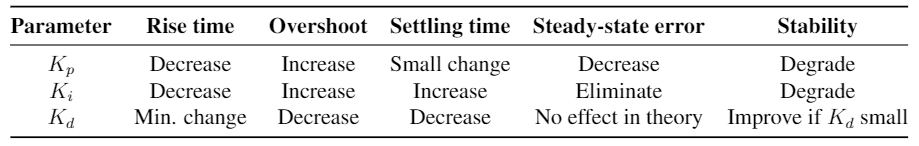

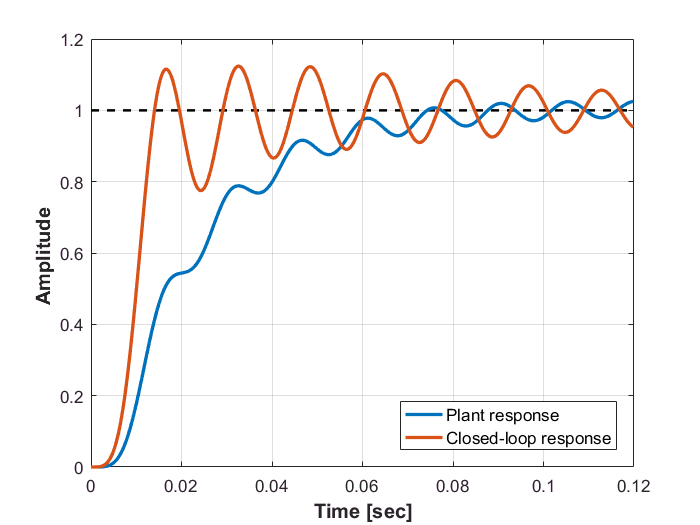

% User values 
%Kpp = 2;
%Kii = 95;
Kpp = 2;
Kii = 95;

Kdd = 0;
Tf = 0;

pid_1 = pid(Kpp,Kii,Kdd,Tf);
T_A = feedback(pid_1*G_plant,1);
[y_PI] =  step(T_A,tt);

figure(2)
p1 = plot([0 tt(end)],[1 1],'k--','linewidth',1.5); grid on, hold on
p2 = plot(tt,y_p,'color',b_d,'linewidth',2);
p4 = plot(tt,y_PI,'color',r_d,'linewidth',2);
ylabel('Amplitude ','fontsize',12,'fontweight','bold'),
xlabel('Time [sec]','fontsize',12,'fontweight','bold'),
legend([p2,p4],{'Plant response','Closed-loop response'},'Location','southEast','fontsize',10)

The step response plot allows to evaluate the plant and closed-loop behavior.  Although, the overshoot reaches a value of 20%, the rise time and settling time values decreased notoriously which are a measure of the system speed. However, the time delay has to be verified. 

info_OL = stepinfo(G_plant);
info_CL = stepinfo(T_A);

OS_OL = round(100*info_OL.Overshoot)/100;
tr_OL = round(10000*info_OL.RiseTime)/10000;
ts_OL = round(10000*info_OL.SettlingTime)/10000;

OS_CL = round(100*info_CL.Overshoot)/100;
tr_CL = round(10000*info_CL.RiseTime)/10000;
ts_CL = round(10000*info_CL.SettlingTime)/10000;

Type = {'Overshoot [%]';'Time rise [sec]';'Settling time [sec]'};
Open_loop   = [OS_OL tr_OL ts_OL]';
Closed_loop = [OS_CL tr_CL ts_CL]';


step_resp = table(Open_loop,Closed_loop,'RowNames',Type)

step_resp =                            Open_loop    Closed_loop
                           _________    ___________

    Overshoot [%]            1.77        12.29     
    Time rise [sec]        0.0366       0.0069     
    Settling time [sec]    0.1289       0.1942     


Using a Bode plot, the frequency response of the plant and the closed-loop (CL) systems are compared. 

- The magnitude of the CL system at low frequencies is around 0 dB (or magnitude = 1), which means that the PI controller improved the response of the Plant to this desired value. This is important because we do not want to affect the amplitude of the response at low frequencies.

-  The time delay $t_d$, is calculated as $t_d =\frac{\phi }{f}$ and plotted to see the effect of the controller in the response. Although the  $t_d$ in the CL system decreased to 15 msec, this value is still somewhat large and the RTHS performance can be compromised.

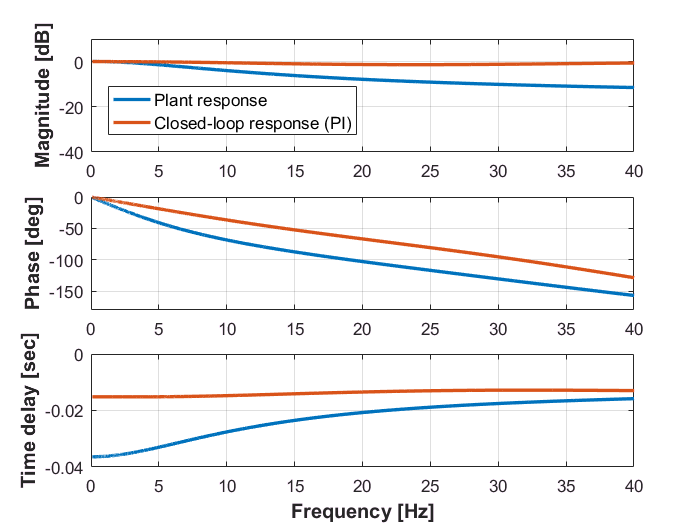

ww = 2*pi*logspace(-1,2,3000);
[MAG,PHASE] = bode(G_plant,ww);
magn = squeeze(MAG);   mag_OL = abs(magn);
pha  = squeeze(PHASE); ang_OL = unwrap(pha);

[MAG,PHASE] = bode(T_A,ww);
magn = squeeze(MAG);   mag_CL = abs(magn);
pha  = squeeze(PHASE); ang_CL = unwrap(pha);

s1 = subplot(3,1,1);
p1 = plot(ww/2/pi,db(mag_OL),'color',b_d,'linewidth',2);  hold on, grid on
p2 = plot(ww/2/pi,db(mag_CL),'color',r_d,'linewidth',2); 
axis([0 40 -40 10])
ylabel('Magnitude [dB]','fontsize',12,'fontweight','bold')

s2 = subplot(3,1,2);
plot(ww/2/pi,ang_OL,'color',b_d,'linewidth',2),  hold on, grid on
plot(ww/2/pi,ang_CL,'color',r_d,'linewidth',2), 
axis([0 40 -180 0])
ylabel('Phase [deg]','fontsize',12,'fontweight','bold')

Td1 = ang_OL'/(2*pi)./ww/(2*pi);        % convert phase lag to time delay in second
DL1 = mean(abs(Td1(2:500)));

Td2 = ang_CL'/(2*pi)./ww/(2*pi);      % convert phase lag to time delay in second
DL2 = mean(abs(Td2(2:500)));

s2 = subplot(3,1,3);
plot(ww/2/pi,Td1,'linewidth',2,'color',b_d); grid on, hold on
plot(ww/2/pi,Td2,'linewidth',2,'color',r_d); grid on, hold on
axis([0 40 -.04 0])
ylabel('Time delay [sec]','fontsize',12,'fontweight','bold')
xlabel('Frequency [Hz]','fontsize',12,'fontweight','bold'), 
legend([p1,p2],{'Plant response','Closed-loop response (PI)'},'Location','southwest','fontsize',10)

The performance of the PI controller is severely limited by the long time-delay and any type of time-delay compensator should be implemented to improve the CL system response.

# Time-delay Compensation

The time and frequency responses of the closed-loop system shown in the preceding section demonstrate that a PI tracking controller alone is not sufficient to achieve acceptable performance. Such poor results are caused by the large time-delay observed. As a result, positive phase should be introduced to the system.  A phase lead compensator, which can be seen as a high-pass filter,  will be designed to obtain an improved control plant response. The disadvantage is an increase in the high-frequency gain, which can amplify high-frequency noise.

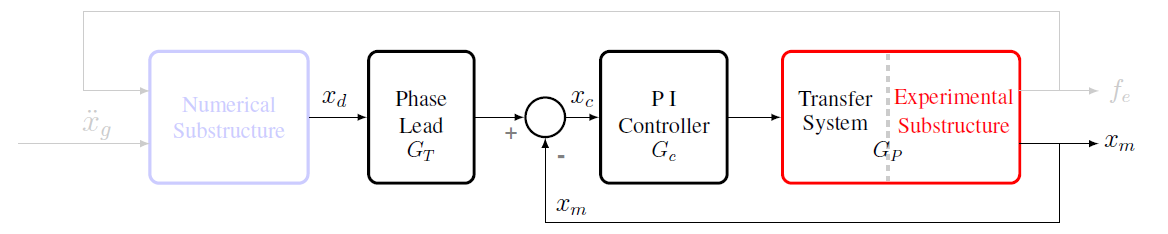

## 1. Bode plot of the open-loop transfer function  $L={ G }_{ p }{ \times G }_{ c }$. 

From the Bode plot, obtain the phase margin and gain margin from the bode plot. The Phase margin is the amount of pure phase delay that can be added before the closed-loop system becomes unstable [2].  Lead compensation is typically used to improve phase margin, thats is why we will include it in the control scheme.

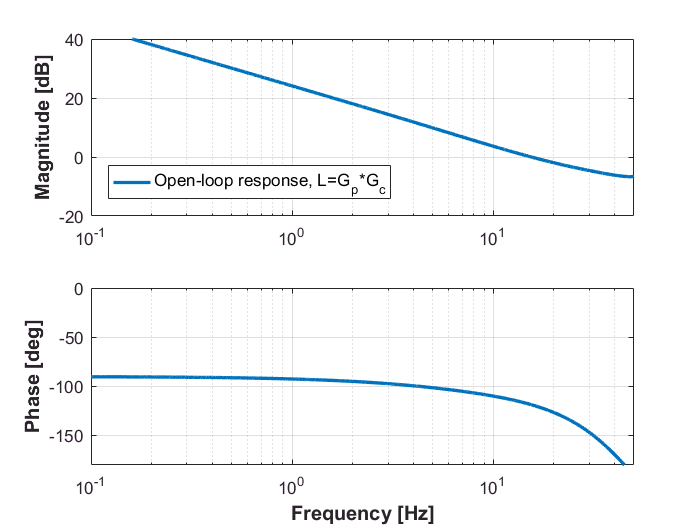

clc,  close all
LL = pid_1*G_plant;                 % Forward-path transfer function (L = Gp*Gc)
ww = 2*pi*logspace(-1,1.7,3000);    % Frequency vector
[MAG,PHASE] = bode(LL,ww);
magn = squeeze(MAG);   mag_LL = abs(magn);
pha  = squeeze(PHASE); ang_LL = unwrap(pha);

[Gm,Pm,Wcg,Wcp] = margin(mag_LL,ang_LL,ww);
fm = Wcp/2/pi;

figure
s1 = subplot(2,1,1);
p1 = semilogx(ww/2/pi,db(mag_LL),'color',b_d,'linewidth',2);  hold on, grid on
axis([0 50 -20 40])
ylabel('Magnitude [dB]','fontsize',12,'fontweight','bold')

s2 = subplot(2,1,2);
semilogx(ww/2/pi,ang_LL,'color',b_d,'linewidth',2),  hold on, grid on
axis([0 50 -180 0])
ylabel('Phase [deg]','fontsize',12,'fontweight','bold')
xlabel('Frequency [Hz]','fontsize',12,'fontweight','bold'), 
legend([p1],{'Open-loop response, L=G_p*G_c'},'Location','southwest','fontsize',10)

## 2. Place zero-pole configuration accordingly 

The phase-lead compensator is reprensted by the transfer function $G_T$.  The pole-zero-gain configuration as is shown in the equation below.


$$G_T =a\frac{s+\frac{1}{\text{aT}}}{s+\frac{1}{T}}$$


The design of this controller is based on how choose adequately the pole-zero pair of $G_T$ with a zero at $\left(\frac{-1}{\text{aT}}\right)$and a pole $\left(\frac{-1}{\text{T}}\right)$. 

- Moving the `zero` between 15 to 30 Hz to improve the rise time and settling time. 

- Moving the `pole` farther away (that is why in the final design the pole is affected by a factor) to reduce the Overshoot but the rise time and seetling time will increase again.

wm = 850 ;           % [rad/sec]
val = 5;             % Include some safety margin [deg]

a = (1+sind(Pm+val))/(1-sind(Pm+val));

TT = 1/(wm*sqrt(a));


Set the corner frequencies $\frac{1}{\text{aT}}$ and $\frac{1}{\text{T}}$  which define the maximum value of the phase $\phi_m$ and the frequncy at which this occurs $\omega_m$. As a rule of thumb, place the zero $\frac{1}{\text{aT}}$ between 15 and 30 Hz to make sure that at low frequency the magnitude of the closed-loop system remains close to 0 dB.

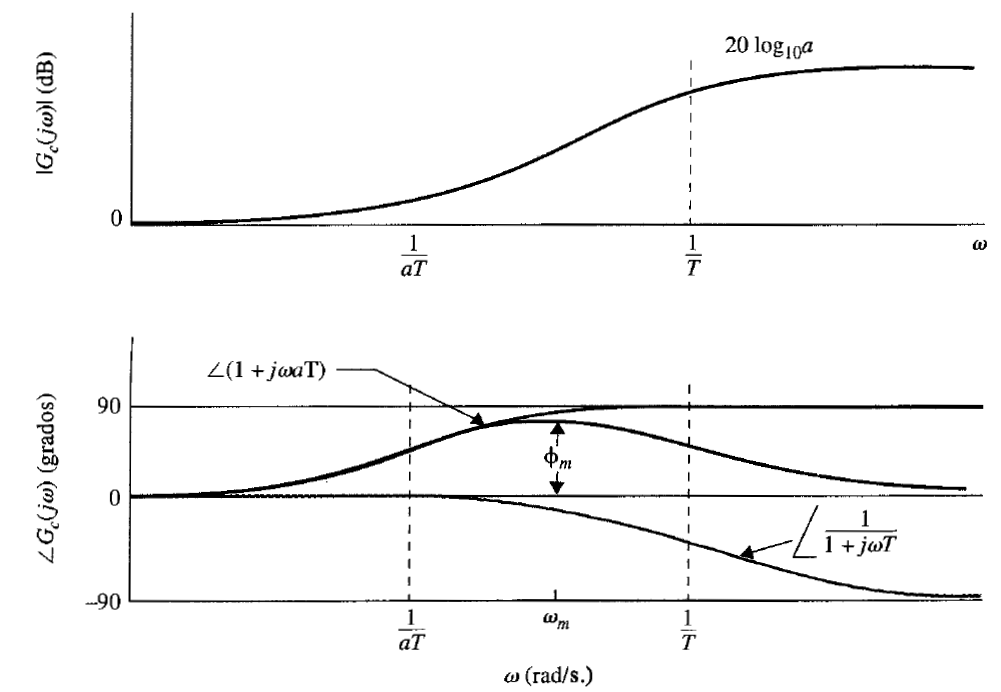 

p_pl = -1/TT ;        % Added pole
z_pl = p_pl/a;        % Added zero
%% 
fac = 2;
p_pl = fac*p_pl;
z_pl = z_pl;
k_pl = a*fac;

[num_pl, den_pl] = zp2tf(z_pl,p_pl,k_pl);
G_T = tf(num_pl,den_pl);
zpk(G_T)


ans =
 
  45.474 (s+178.3)
  ----------------
      (s+8106)
 
Continuous-time zero/pole/gain model.



The frequency response of the delay compensator is shown below.  From the Bode plot, it can be seen that the magnitude of $G_T$is around 0 dB at low frequency, and positive time delay will be added to the system. 

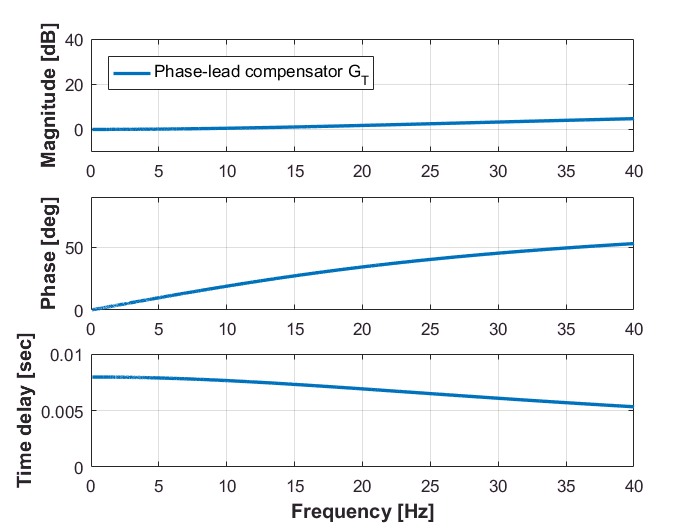


[MAG,PHASE] = bode(G_T,ww);
magn = squeeze(MAG);   mag_PL = abs(magn);
pha  = squeeze(PHASE); ang_PL = unwrap(pha);

figure
subplot(3,1,1);
p1 = plot(ww/2/pi,db(mag_PL),'color',b_d,'linewidth',2);  hold on, grid on
axis([0 40 -10 40])
ylabel('Magnitude [dB]','fontsize',12,'fontweight','bold')

subplot(3,1,2);
plot(ww/2/pi,ang_PL,'color',b_d,'linewidth',2),  hold on, grid on
axis([0 40 0 90])
ylabel('Phase [deg]','fontsize',12,'fontweight','bold')

legend([p1],{'Phase-lead compensator G_T'},'Location','northwest','fontsize',10)

TdPL = ang_PL'/(2*pi)./ww/(2*pi);      % convert phase lag to time delay in second
DLPL = mean(abs(TdPL(2:500)));

subplot(3,1,3);
plot(ww/2/pi,TdPL,'linewidth',2,'color',b_d); grid on, hold on
axis([0 40  0 .01])
ylabel('Time delay [sec]','fontsize',12,'fontweight','bold')
xlabel('Frequency [Hz]','fontsize',12,'fontweight','bold'), 

## 3. Response comparison of the Plant, and CL controllers

To compare the performance of the PI, and the PI + phase-lead (PL) controllers,  frequency and time domain responses are evaluated.  The PI+PL scheme provides much faster response descreasing the time delay, however the overshoot is also affected.  The user should check the stability margins and see how much delay can be added without compromise the stabiltity of the CL system. 

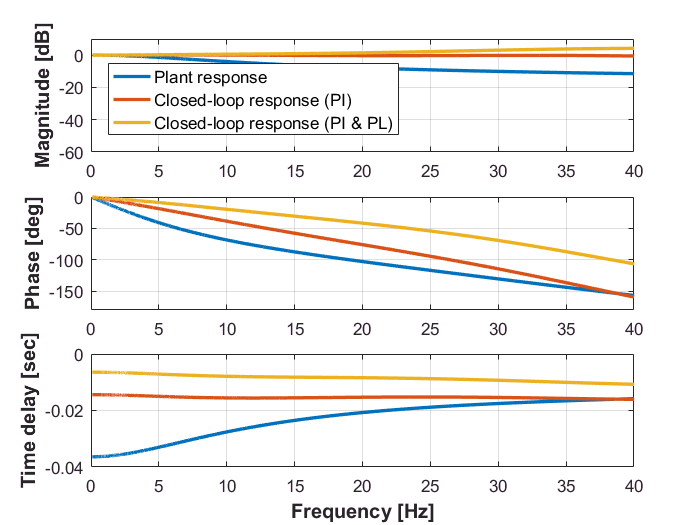

ww = 2*pi*logspace(-1,2,3000);
[MAG,PHASE] = bode(G_plant,ww);
magn = squeeze(MAG);   mag_OL = abs(magn);
pha  = squeeze(PHASE); ang_OL = unwrap(pha);

[MAG,PHASE] = bode(T_A,ww);
magn = squeeze(MAG);   mag_CL = abs(magn);
pha  = squeeze(PHASE); ang_CL = unwrap(pha);

T_AF = G_T* T_A;
[MAG,PHASE] = bode(T_AF,ww);
magn = squeeze(MAG);   mag_F = abs(magn);
pha  = squeeze(PHASE); ang_F = unwrap(pha);

figure
s1 = subplot(3,1,1);
p1 = plot(ww/2/pi,db(mag_OL),'color',b_d,'linewidth',2);  hold on, grid on
p2 = plot(ww/2/pi,db(mag_CL),'color',r_d,'linewidth',2); 
p3 = plot(ww/2/pi,db(mag_F),'color',y_d,'linewidth',2); 
axis([0 40 -60 10])
ylabel('Magnitude [dB]','fontsize',12,'fontweight','bold')

s2 = subplot(3,1,2);
plot(ww/2/pi,ang_OL,'color',b_d,'linewidth',2),  hold on, grid on
plot(ww/2/pi,ang_CL,'color',r_d,'linewidth',2), 
plot(ww/2/pi,ang_F,'color',y_d,'linewidth',2),
axis([0 40 -180 0])
ylabel('Phase [deg]','fontsize',12,'fontweight','bold')

Td1 = ang_OL'/(2*pi)./ww/(2*pi);        % convert phase lag to time delay in second
DL1 = mean(abs(Td1(2:500)));

Td2 = ang_CL'/(2*pi)./ww/(2*pi);        % convert phase lag to time delay in second
DL2 = mean(abs(Td2(2:500)));

Td3 = ang_F'/(2*pi)./ww/(2*pi);        % convert phase lag to time delay in second
DL3 = mean(abs(Td3(2:500)));

s2 = subplot(3,1,3);
plot(ww/2/pi,Td1,'linewidth',2,'color',b_d); grid on, hold on
plot(ww/2/pi,Td2,'linewidth',2,'color',r_d)
plot(ww/2/pi,Td3,'linewidth',2,'color',y_d)
axis([0 40 -.04 0])
ylabel('Time delay [sec]','fontsize',12,'fontweight','bold')
xlabel('Frequency [Hz]','fontsize',12,'fontweight','bold'), 
legend([p1,p2,p3],{'Plant response','Closed-loop response (PI)','Closed-loop response (PI & PL)'},'Location','southwest','fontsize',10)

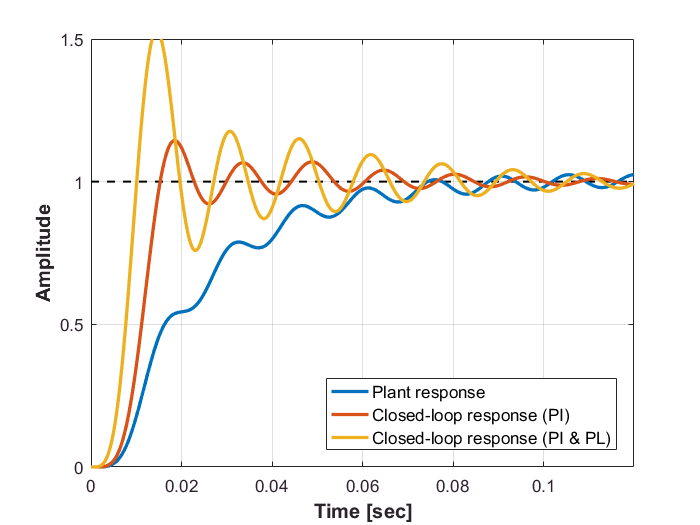

[y_p] =  step(G_plant,tt);
[y_PI] =  step(T_A,tt);
[y_Par] = step(T_AF,tt);

figure
p1 = plot([0 tt(end)],[1 1],'k--','linewidth',1.2); grid on, hold on
p1 = plot(tt,y_p,'color',b_d,'linewidth',2);
p2 = plot(tt,y_PI,'color',r_d,'linewidth',2);
p3 = plot(tt,y_Par,'color',y_d,'linewidth',2);
axis([0 tt(end) 0 1.5])
xlabel('Time [sec]','fontsize',12,'fontweight','bold')
ylabel('Amplitude','fontsize',12,'fontweight','bold'), 
legend([p1,p2,p3],{'Plant response','Closed-loop response (PI)','Closed-loop response (PI & PL)'},'Location','southeast','fontsize',10)

Save your controller design:

time = clock;
time_test = strcat(num2str(time(1)),'_',... % Returns year 
    num2str(time(2)),'_',... % Returns month 
    num2str(time(3)),'_',... % Returns day 
    num2str(time(4)),'_',... % returns hour 
    num2str(time(5)),'_',... % returns min 
    num2str(fix(time(6)))) ; 

save(strcat('.\Controllers\Controller_',time_test), 'pid_1','G_T');


## Disclaimer

Here, a simple PID controller design procedure is summarized through an illustrative example. However, a better controller in terms of performance and robustness is recommended to conduct actual RTHS tests.

## Bibliography

[1] Aström, K. J., & Murray, R. M. (2010. "Feedback systems: an introduction for scientists and engineers", Princeton university press.

[2] Golnaraghi, F., & Kuo, B. C. (2010). "Automatic control systems", 9th Edition, John Wiley & Sons.